# Part 0

load("contdata95.mat")
%Y = [Y, [Y(:,2:end),zeros(length(Y),1)], [Y(:,3:end), zeros(length(Y),2)], [Y(:,4:end), zeros(length(Y),3)], [Y(:,5:end), zeros(length(Y),4)], [Y(:,6:end), zeros(length(Y),5)], [Y(:,7:end), zeros(length(Y),6)], [Y(:,8:end), zeros(length(Y),7)], [Y(:,9:end), zeros(length(Y),8)], [Y(:,10:end), zeros(length(Y),9)]];
%test = [zeros(6,95);Y(1:length(Y)-6, :)]
Y = [Y, [zeros(1,95);Y(1:length(Y)-1, :)], [zeros(2, 95);Y(1:length(Y)-2, :)], [zeros(3,95);Y(1:length(Y)-3, :)], [zeros(4, 95);Y(1:length(Y)-4, :)], [zeros(5,95);Y(1:length(Y)-5, :)], [zeros(6, 95);Y(1:length(Y)-6, :)], [zeros(7, 95);Y(1:length(Y)-7, :)], [zeros(8, 95);Y(1:length(Y)-8, :)], [zeros(9, 95);Y(1:length(Y)-9, :)]];

Y = [ones(length(Y), 1), Y];
Xtrain = Y(1:round(length(X)/2),:);
Xtest = Y(round(length(X)/2):end,:);
Ytrain = X(1:round(length(Y)/2),:);
Ytest = X(round(length(Y)/2:end),:);

# Part 1

%B = zeros(15707,4);
n = length(Xtrain);
B= (Xtrain.'*Xtrain)^(-1)*Xtrain.'*Ytrain;
Y_pred = Xtest*B

Y_pred =   -23.8088   -8.9978    1.5858   12.5459
  -13.6188   -1.4380   71.2060   -3.3762
   -3.1154   -0.9091   23.3308  -27.8407
   -3.7870   -8.9558   -4.7202   -5.6688
   -8.4207   -9.1741  -22.7114  -31.6327
   -0.4113    8.5007   39.0215  138.4543
   39.0422   36.3439  350.2704  355.0029
   73.6068   51.9422  381.9509  101.8623
   88.1723   39.2803  183.4245  -73.8314
   68.3624   13.0981   67.9600  -50.3662


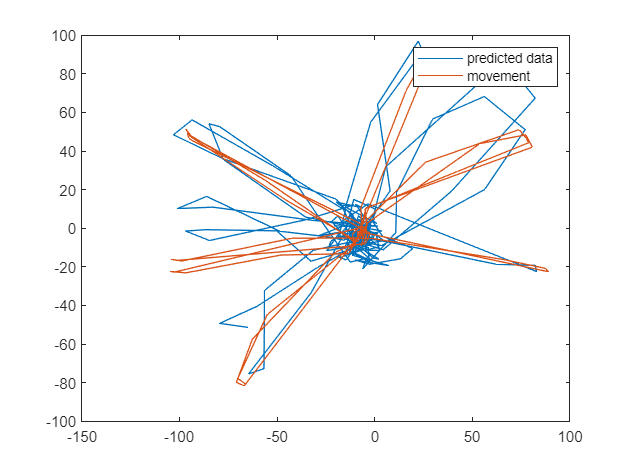

%subplot(3,1,1)
figure
plot(Y_pred(150:350,1),Y_pred(150:350,2))
hold on
plot(Ytest(150:350,1), Ytest(150:350,2))
legend('predicted data','movement')

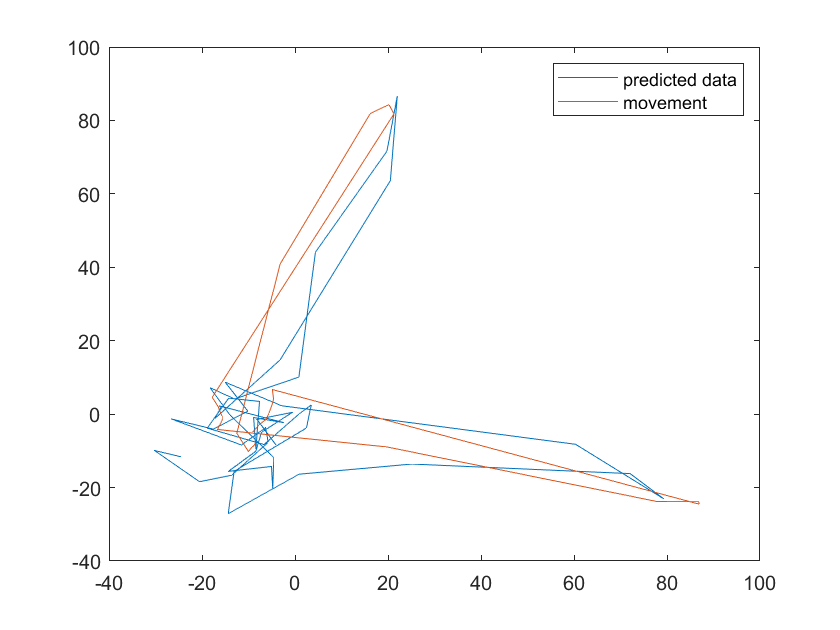

figure
plot(Y_pred(100:150,1),Y_pred(100:150,2))
hold on
plot(Ytest(100:150,1),Ytest(100:150,2))
legend('predicted data','movement')
hold off

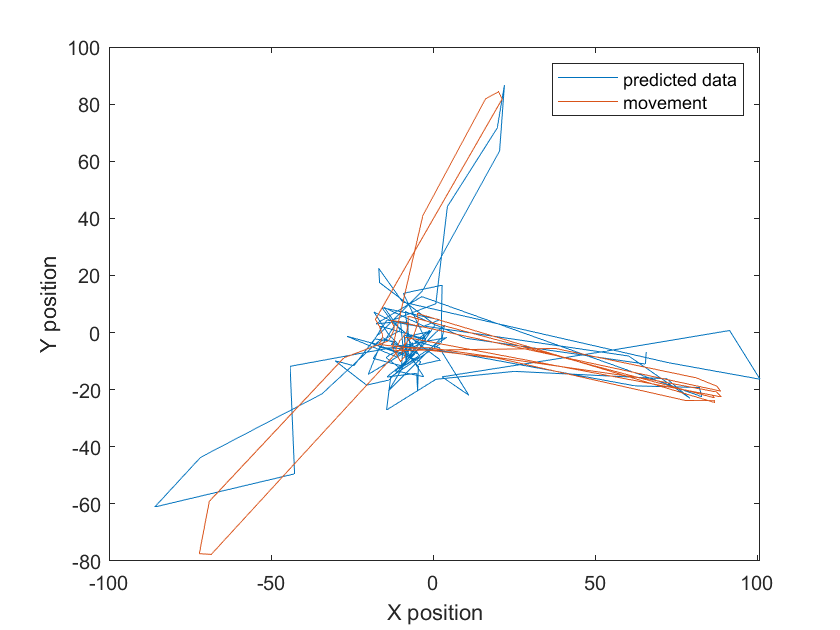

figure
plot(Y_pred(50:170,1),Y_pred(50:170,2))
hold on
plot(Ytest(50:170,1), Ytest(50:170,2))
legend('predicted data','movement')
xlabel('X position')
ylabel('Y position')
hold off

%do the x and y coordinates separately
t = Xtest*B;
% mse = (t(:,1)-Ytest(:,1))'*(t(:,1)-Ytest(:,1))
% mse = (t(:,2)-Ytest(:,2))'*(t(:,2)-Ytest(:,2))
% mse = (t(:,3)-Ytest(:,3))'*(t(:,3)-Ytest(:,3))
% mse = (t(:,4)-Ytest(:,4))'*(t(:,4)-Ytest(:,4))
mse = diag((Xtest*B-Ytest)'*(Xtest*B-Ytest))

mse = 	1.0e+07 *

    0.2032
    0.2136
    4.7155
    4.6107


diag(corr(Ytest,Y_pred))

ans =     0.9141
    0.8859
    0.8696
    0.8387


% corr(Ytest(:,1),Y_pred(:,1))
% corr(Ytest(:,2),Y_pred(:,2))
% corr(Ytest(:,3),Y_pred(:,3))
% corr(Ytest(:,4),Y_pred(:,4))

# Part 2

for ridge: Multiply lambda by n

n = length(Xtrain);
lambda = linspace(0,0.1,15);
I = eye(951);

for i = [1:1:15]
    B = (Xtrain'*Xtrain+n*lambda(i)*I)^-1*Xtrain'*Ytrain;
    mse_lambda(i,:) = diag((Xtest*B-Ytest)'*(Xtest*B-Ytest)+lambda(i)*B'*B);

end


[mins,best_index] = min(mse_lambda);
best_lambda = lambda(mean(best_index))

best_lambda = 0.0286

B = (Xtrain'*Xtrain+n*best_lambda*I)^-1*Xtrain'*Ytrain;
Y_pred = Xtest*B

Y_pred =   -23.2164   -9.7857   13.7428   12.9273
  -12.7200   -2.4444   79.2696   -7.6488
   -3.2443   -1.7356   15.2058  -28.9405
   -5.8151  -10.2820  -15.2297   -6.4156
  -11.0900  -10.4015  -22.8541  -31.5268
   -1.8237    7.7516   46.1245  133.0615
   39.0414   35.7863  355.4039  349.3704
   73.8743   51.1583  384.4807  103.5723
   89.1307   38.9394  189.1318  -71.5295
   68.9195   13.5174   70.9415  -49.8902


mse = diag((Xtest*B-Ytest)'*(Xtest*B-Ytest))

mse = 	1.0e+07 *

    0.2025
    0.2132
    4.7008
    4.5985


diag(corr(Ytest,Y_pred))

ans =     0.9144
    0.8860
    0.8699
    0.8391


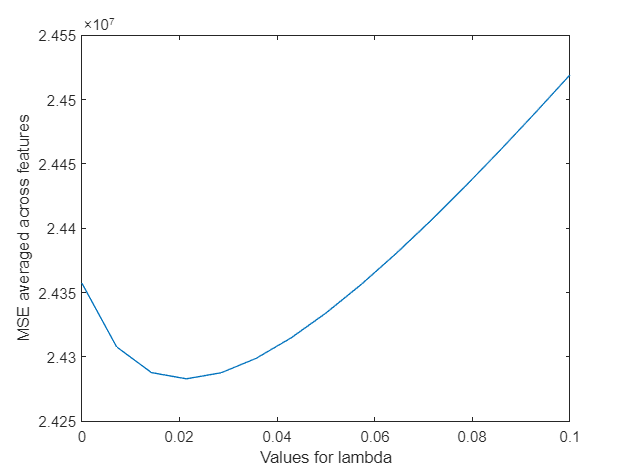

plot(lambda, mean(mse_lambda'))
xlabel('Values for lambda')
ylabel('MSE averaged across features')